**TASK1**

**Loading and Converting Video Frames**

This section loads the video file, extracts each frame, and converts the frames from RGB to grayscale. The grayscale frames are stored in a cell array for further processing.

clc; clear; close all;
%%mkdir('Results');
%% Load Video
video = VideoReader('sample.mp4');

frames = {};
i = 1;

while hasFrame(video)
    frame = readFrame(video);
    gray = rgb2gray(frame);
    frames{i} = gray;
    i = i + 1;
end

numFrames = length(frames);
disp(['Total Frames: ', num2str(numFrames)]);

Total Frames: 1016


Task 2 — Determine Image Size

The image dimensions were determined using the `size()` function. This is important because subsequent measurements are obtained in pixels and later converted into physical units using calibration.

[H, W] = size(frames{1});
%
disp(['Height: ', num2str(H), ', Width: ', num2str(W)]);

Height: 512, Width: 800


**TASK 3**

The image was calibrated using the known 2 mm scale bar, which corresponds to 50 pixels. The resulting calibration factor is 0.04 mm/pixel and is used to convert pixel measurements into physical dimensions.

%% Calibration

scale_pixels = 50;
scale_mm = 2;

mm_per_pixel = scale_mm / scale_pixels;

disp(['Calibration: ', num2str(mm_per_pixel), ' mm/pixel']);

Calibration: 0.04 mm/pixel


TASK 4

The image was calibrated using the known 2 mm scale bar, which corresponds to 50 pixels. The resulting calibration factor is 0.04 mm/pixel and is used to convert pixel measurements into physical dimensions.

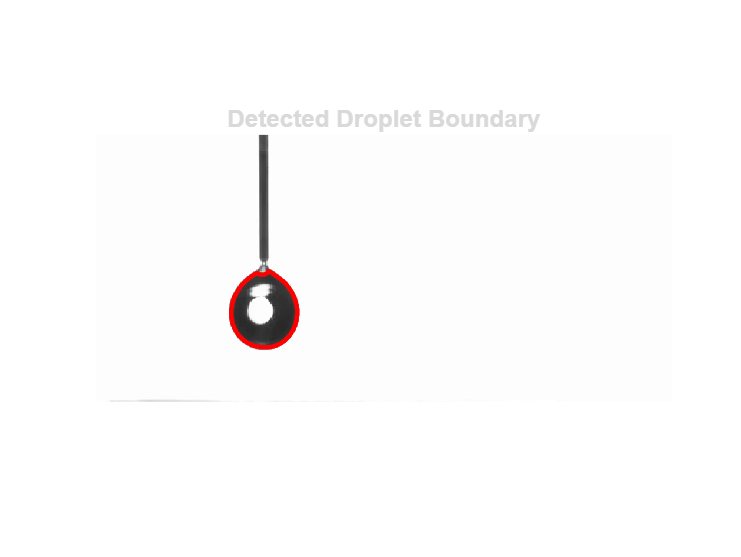

%% Task 4 - Detect Droplet Boundary

bbox_frame1 = [];
droplet_frame1 = [];

for i = 1:numFrames

    frame = frames{i};

    frame = frame(80:450, :);

    blur = imgaussfilt(frame, 2);

    bw = imbinarize(blur, 0.35);
    bw = ~bw;

    bw = bwareaopen(bw, 1500);

    cc = bwconncomp(bw);

    if cc.NumObjects == 0
        continue;
    end

    numPixels = cellfun(@numel, cc.PixelIdxList);
    [~, idx] = max(numPixels);

    droplet = false(size(bw));
    droplet(cc.PixelIdxList{idx}) = true;

    props = regionprops(droplet, 'BoundingBox', 'Centroid');
    bbox = props.BoundingBox;

    if i == 1
        bbox_frame1 = bbox;
        droplet_frame1 = droplet;
    end

end

%% Figure 2 - Detected Droplet Boundary

frame = frames{1};
frame = frame(80:450, :);

B = bwboundaries(droplet_frame1);

figure;
imshow(frame);
hold on;

plot(B{1}(:,2), B{1}(:,1), 'r', 'LineWidth', 2);

title('Detected Droplet Boundary');
set(gcf,'Color','w');

exportgraphics(gcf, fullfile('Results','Figure2.jpg'), ...
    'Resolution', 300);

TASK 5

The projected area of the detected droplet was calculated by counting its pixels and converting the result into mm² using the calibration factor. This represents the two-dimensional area of the droplet visible in the image.

%% Droplet Area

area_pixels = numel(cc.PixelIdxList{idx});

area_mm2 = area_pixels * mm_per_pixel^2;

disp(['Droplet Area: ', num2str(area_pixels), ' pixels']);

Droplet Area: 4730 pixels


disp(['Droplet Area: ', num2str(area_mm2), ' mm^2']);

Droplet Area: 7.568 mm^2


TASK 6

A bounding rectangle was fitted around the detected droplet using `regionprops`. The rectangle provides the horizontal and vertical dimensions of the droplet.

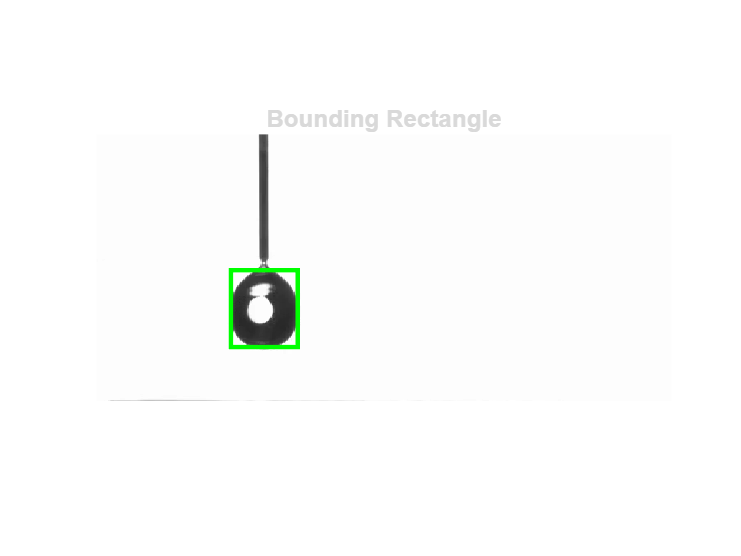

%% Figure 3 - Bounding Rectangle

frame = frames{1};
frame = frame(80:450, :);

figure;
imshow(frame);
hold on;

rectangle('Position', bbox_frame1, ...
    'EdgeColor', 'g', 'LineWidth', 2);

title('Bounding Rectangle');
set(gcf,'Color','w');

exportgraphics(gcf, fullfile('Results','Figure3.jpg'), ...
    'Resolution', 300);

TASK 7

The droplet's horizontal and vertical diameters were obtained from its bounding box for each frame and converted from pixels to millimetres. Both diameters were plotted against time to observe droplet deformation during impact and rebound.

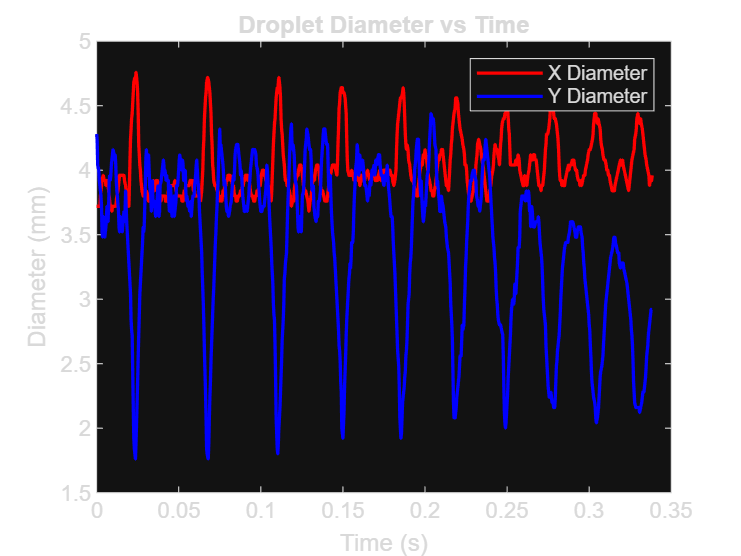

%% Droplet Diameter Evolution

x_diam = zeros(1, numFrames);
y_diam = zeros(1, numFrames);

for i = 1:numFrames

    frame = frames{i};

    frame = frame(80:450, :);

    blur = imgaussfilt(frame, 2);

    bw = imbinarize(blur, 0.35);
    bw = ~bw;

    bw = bwareaopen(bw, 1500);

    cc = bwconncomp(bw);

    if cc.NumObjects == 0
        continue;
    end

    numPixels = cellfun(@numel, cc.PixelIdxList);
    [~, idx] = max(numPixels);

    droplet = false(size(bw));
    droplet(cc.PixelIdxList{idx}) = true;

    props = regionprops(droplet, 'BoundingBox');
    bbox = props.BoundingBox;

    x_diam(i) = bbox(3) * mm_per_pixel;
    y_diam(i) = bbox(4) * mm_per_pixel;

end

%% Time

time = (0:numFrames-1) / 3000;

%% Plot Diameter

figure;

plot(time, x_diam, 'r', 'LineWidth', 1.5);
hold on;

plot(time, y_diam, 'b', 'LineWidth', 1.5);

legend('X Diameter','Y Diameter');

xlabel('Time (s)');
ylabel('Diameter (mm)');

title('Droplet Diameter vs Time');

set(gcf,'Color','w');

exportgraphics(gcf, fullfile('Results','Figure4.jpg'), 'Resolution', 300);

TASK 8

The droplet volume was estimated by assuming a spherical shape and using the measured X-diameter. The estimated volume was plotted against time to study its variation during impact and rebound.

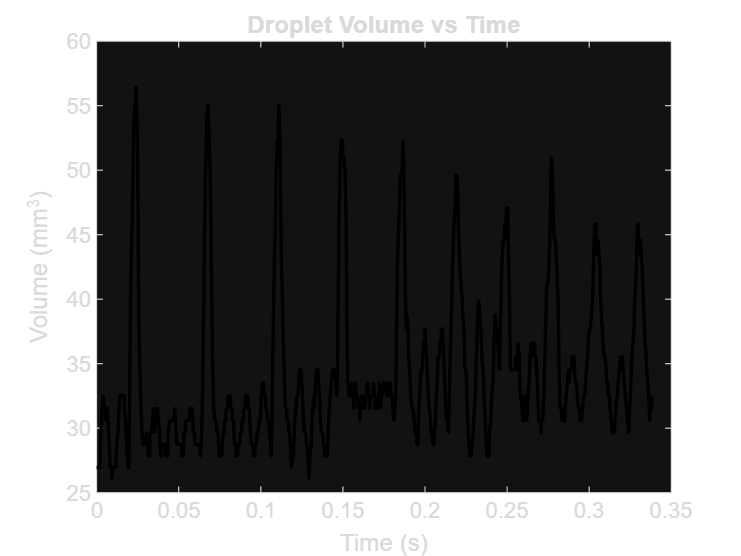

%% Volume

volume = (4/3)*pi*(x_diam/2).^3;

figure;
plot(time, volume, 'k', 'LineWidth', 1.5);

xlabel('Time (s)');
ylabel('Volume (mm^3)');

title('Droplet Volume vs Time');

set(gcf,'Color','w');

exportgraphics(gcf, fullfile('Results','Figure5.jpg'), 'Resolution', 300);

TASK 9

The droplet centroid was calculated for each frame using `regionprops`. Its vertical position was converted to millimetres and plotted against time to track the droplet's motion.

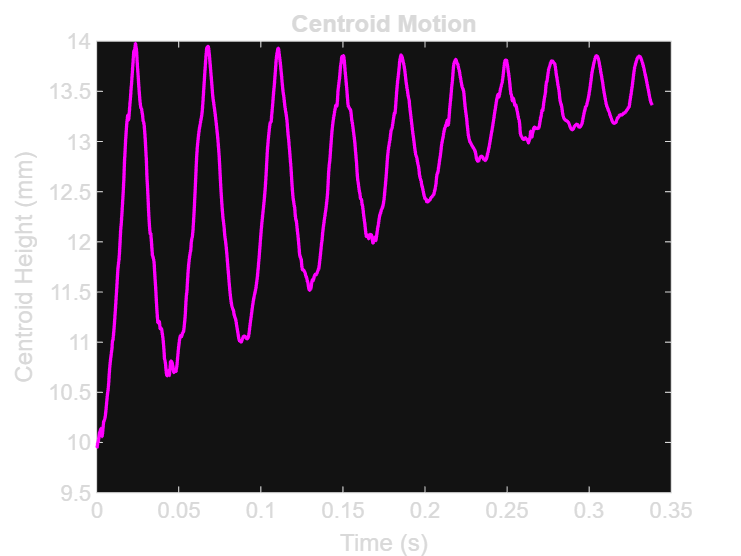

%% Centroid Motion

centroid_y = zeros(1, numFrames);

for i = 1:numFrames

    frame = frames{i};

    frame = frame(80:450, :);

    blur = imgaussfilt(frame, 2);

    bw = imbinarize(blur, 0.35);
    bw = ~bw;

    bw = bwareaopen(bw, 1500);

    cc = bwconncomp(bw);

    if cc.NumObjects == 0
        continue;
    end

    numPixels = cellfun(@numel, cc.PixelIdxList);
    [~, idx] = max(numPixels);

    droplet = false(size(bw));
    droplet(cc.PixelIdxList{idx}) = true;

    props = regionprops(droplet, 'Centroid');

    centroid_y(i) = props.Centroid(2) * mm_per_pixel;

end

%% Plot Centroid Motion

figure;

plot(time, centroid_y, 'm', 'LineWidth', 1.5);

xlabel('Time (s)');
ylabel('Centroid Height (mm)');

title('Centroid Motion');

set(gcf,'Color','w');

exportgraphics(gcf, fullfile('Results','Figure6.jpg'), 'Resolution', 300);

TASK 10

The top-most and bottom-most droplet positions were obtained from the minimum and maximum pixel row coordinates. Their positions were converted to millimetres and plotted against time to observe droplet deformation.

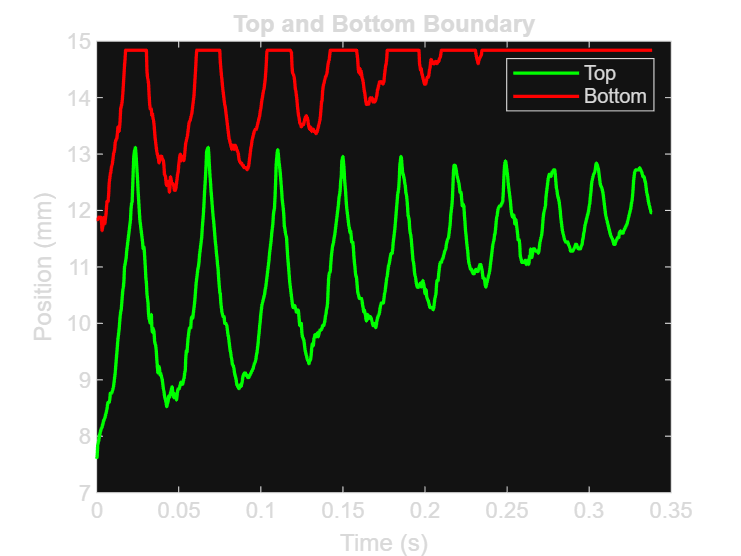

%% Top and Bottom Boundary

top_y = zeros(1, numFrames);
bottom_y = zeros(1, numFrames);

for i = 1:numFrames

    frame = frames{i};

    frame = frame(80:450, :);

    blur = imgaussfilt(frame, 2);

    bw = imbinarize(blur, 0.35);
    bw = ~bw;

    bw = bwareaopen(bw, 1500);

    cc = bwconncomp(bw);

    if cc.NumObjects == 0
        continue;
    end

    numPixels = cellfun(@numel, cc.PixelIdxList);
    [~, idx] = max(numPixels);

    droplet = false(size(bw));
    droplet(cc.PixelIdxList{idx}) = true;

    [row, ~] = find(droplet);

    if ~isempty(row)
        top_y(i) = min(row) * mm_per_pixel;
        bottom_y(i) = max(row) * mm_per_pixel;
    end

end

%% Plot Top and Bottom Boundary

figure;

plot(time, top_y, 'g', 'LineWidth', 1.5);
hold on;

plot(time, bottom_y, 'r', 'LineWidth', 1.5);

legend('Top','Bottom');

xlabel('Time (s)');
ylabel('Position (mm)');

title('Top and Bottom Boundary');

set(gcf,'Color','w');

exportgraphics(gcf, fullfile('Results','Figure7.jpg'), 'Resolution', 300);

TASK 11

Bounce locations were identified from the minima of the centroid trajectory using `findpeaks(-centroid_y)`. The detected locations were marked on the plot and counted to estimate the total number of bounces.

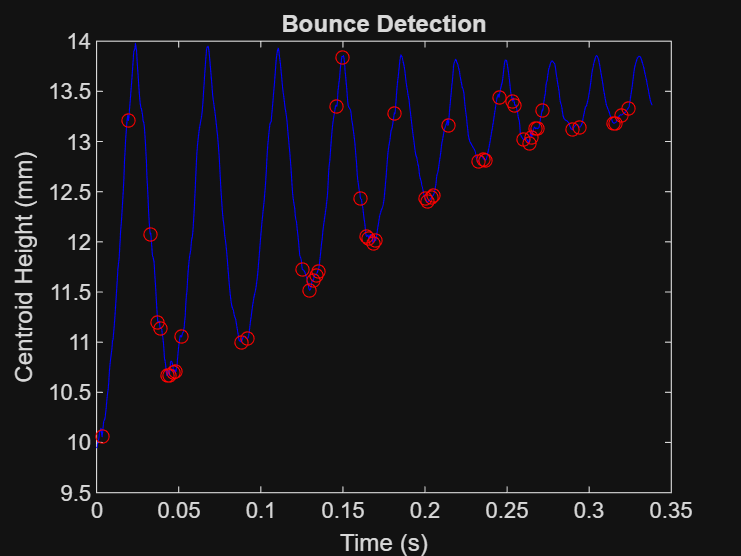

%% Bounce Detection

[pks, locs] = findpeaks(-centroid_y);

figure;

plot(time, centroid_y, 'b');
hold on;

plot(time(locs), centroid_y(locs), 'ro');

xlabel('Time (s)');
ylabel('Centroid Height (mm)');

title('Bounce Detection');


num_bounces = length(locs);

disp(['Number of bounces: ', num2str(num_bounces)]);

Number of bounces: 48


**TASK 12**

**Overall Discussion**

The droplet changes its shape when it hits the superhydrophobic surface. During impact, it spreads mainly in the horizontal direction and becomes flatter. After impact, it starts to become round again as it moves upward.

Before impact, the droplet has gravitational potential energy and gains kinetic energy while falling. During impact, some of this energy is used to deform the droplet, while some energy is lost. During rebound, part of the stored energy helps the droplet move upward again.

The droplet's ability to rebound from the surface shows the water-repellent nature of the superhydrophobic surface. The extracted diameter, centroid and boundary measurements help us understand the droplet's motion and deformation.

However, the results can have errors due to image noise, incorrect threshold selection, imperfect boundary detection and the assumption of a spherical shape while calculating volume. Calibration errors can also affect the measurements.

The analysis can be improved by using better image segmentation, more accurate calibration, improved boundary tracking and a method that considers the actual shape of the droplet when calculating its volume.